# Análise e síntese de Fourier

clear all;
clc;
close all;

## Modelando sinal g(t)

A1 = 1;
A2 = 0;
tau1 = 0.5;
tau2 = 0.5;

To = tau1 + tau2;
fo = inv(To);
wo = 2*pi/To;



## Cáuculo das projeções

syms n t

Ip = int(A1*cos(n*wo*t),t,0,tau1)

$$Ip = \frac{\sin\left(\pi \,n\right)}{2\,n\,\pi }$$

In = int(A2*cos(n*wo*t),t,tau1,0)

$$In = 0$$

dnc = int(cos(n*wo*t)^2,t,0,To)

$$dnc = \frac{\sin\left(4\,\pi \,n\right)}{8\,n\,\pi }+\frac{1}{2}$$


an = (Ip + In)/dnc

$$an = \frac{\sin\left(\pi \,n\right)}{2\,n\,\pi \,\left(\frac{\sin\left(4\,\pi \,n\right)}{8\,n\,\pi }+\frac{1}{2}\right)}$$


Ips = int(A1*sin(n*wo*t),t,0,tau1)

$$Ips = \frac{{\sin\left(\frac{\pi \,n}{2}\right)}^{2}}{n\,\pi }$$

Ins = int(A2*sin(n*wo*t),t,tau1,To)

$$Ins = 0$$

dns = int(sin(n*wo*t)^2,t,0,To)

$$dns = \frac{1}{2}-\frac{\sin\left(4\,\pi \,n\right)}{8\,n\,\pi }$$

bn = (Ips + Ins)/dns

$$bn = -\frac{{\sin\left(\frac{\pi \,n}{2}\right)}^{2}}{n\,\pi \,\left(\frac{\sin\left(4\,\pi \,n\right)}{8\,n\,\pi }-\frac{1}{2}\right)}$$

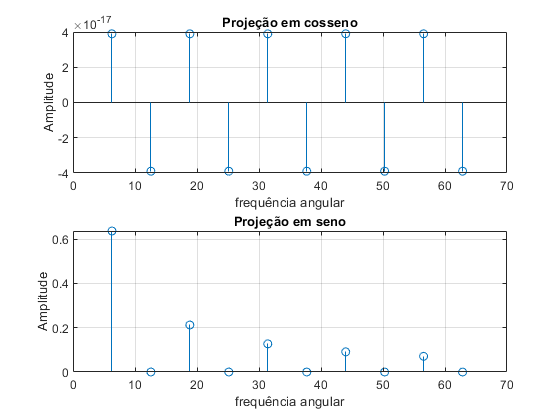


N =10;

n= [1:1:N];


a = eval(an);
b = eval(bn);

figure(1)

subplot(2,1,1); stem(n*wo,a);
grid;
title('Projeção em cosseno');
xlabel('frequência angular');
ylabel('Amplitude');

subplot(2,1,2); stem(n*wo,b);grid;
title('Projeção em seno');
xlabel('frequência angular');
ylabel('Amplitude');

## Síntese de Fourier

auxc = 0;
auxs = 0;
R = To/1000;
tempo = [0:R:To];
for k=1:N
    
    auxc = auxc + a(k)*cos(n(k)*wo*tempo);
    auxs = auxs + b(k)*sin(n(k)*wo*tempo);
end
ao = (A1*tau1 + A2*tau2)/To

ao = 0.5000

gt = ao  + auxs;
qt= (square(2*pi*tempo,50) + 1) * 0.5;

figure(2)

plot(tempo,gt);
hold;

Current plot held


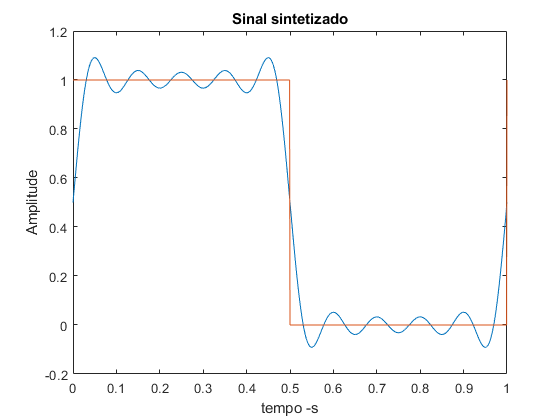

plot(tempo,qt);
title('Sinal sintetizado');
xlabel('tempo -s');
ylabel('Amplitude');